error = -0.1:0.01:0.1;

error_threshold = 0.05;
friction_threshold = 0.21;

comp = zeros(length(error),1)

comp =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


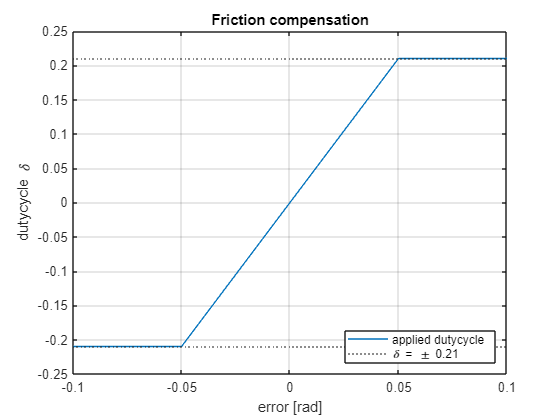


for i = 1:length(error)
    e = error(i);
if abs(e) > error_threshold
    comp(i) = friction_threshold * sign(e);
else 
    comp(i) = e / error_threshold * friction_threshold;
end
end

figure;
plot(error, comp)
yline([-0.21, 0.21], ':')
legend("applied dutycycle", "\delta = \pm 0.21", 'location', 'southeast')
grid on;
xlabel("error [rad]")
ylabel("dutycycle \delta")
title("Friction compensation")